## Load data

clear;

cupId = 2;


% Load file and cup configurations
[file, cup] = func_loadBasicParams(cupId);

% Data cofigurations
config.data.ch = 2;
config.data.rate = 48000; 

config.data.unit = 20; 
config.data.nTrial = 4; 

config.data.nData = (ceil(cup.maxAmount / config.data.unit) + 1) * config.data.nTrial; 

matName = [num2str(cupId), 'cup.mat'];

% % Load data
% if exist(matName) == 0
%     data = struct(); 
%     for cnt = 1:config.data.nData
%         data(cnt).amount = floor((cnt - 1) / config.data.nTrial) * config.data.unit;     
%         [raw, fs] = audioread([file.path, sprintf(file.name, cupId, data(cnt).amount, ...
%             rem(cnt - 1, config.data.nTrial) + 1)]); 
%         raw = raw(:, config.data.ch); 
%         data(cnt).raw = resample(raw, config.data.rate, fs); 
%     end
%     
%     save(matName, 'data');
% else
%     load(matName);
% end

% File Checker
list=dir();
for i=1:length(list)
	isFileExist=strcmp(matName,list(i).name);
	if(isFileExist) break; 
    end
end

% Load data
if ~isFileExist
    data = struct();
    for cnt = 1:config.data.nData
        data(cnt).amount = floor((cnt - 1) / config.data.nTrial) * config.data.unit;
        [raw, fs] = audioread([file.path, sprintf(file.name, cupId, data(cnt).amount, ...
            rem(cnt - 1, config.data.nTrial) + 1)]);

        raw = raw(:, config.data.ch);
        data(cnt).raw = raw;
    end
    save(matName, 'data');
else
    load(matName);
end

## Detect singing sounds

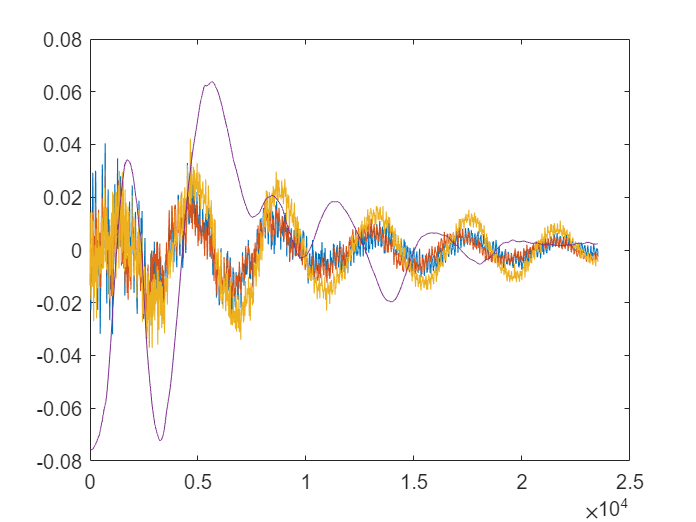

% Detection configurations
% config.detect.interval = ceil(config.data.rate * .01):ceil(config.data.rate * .5 - 1);

% Detect singing sounds based on amplitude
for cnt = 1:config.data.nData
    cur = data(cnt).raw;
    PeakFind = func_calcEnergy(data(cnt).raw, config.data.rate * 0.1); % calcEnergy

    PeakFind = PeakFind / max(abs(PeakFind)); % normalize

    figure
%     findpeaks(PeakFind, 'MinPeakDistance', config.data.rate * 0.5, 'NPeaks', 10, 'MinPeakHeight', 0.01);
    [pks, locs] = findpeaks(PeakFind, 'MinPeakDistance', config.data.rate * 0.5, 'NPeaks', 10, 'MinPeakHeight', 0.01);

    for cnt2 = 1:length(locs)
        data(cnt).detected(:,cnt2) = cur(locs(cnt2) + (config.data.rate * .01) ...
            : locs(cnt2) + (config.data.rate * .5 - 1));
    end
    

end
figure
plot(data(1).detected)

## Extract spectrums

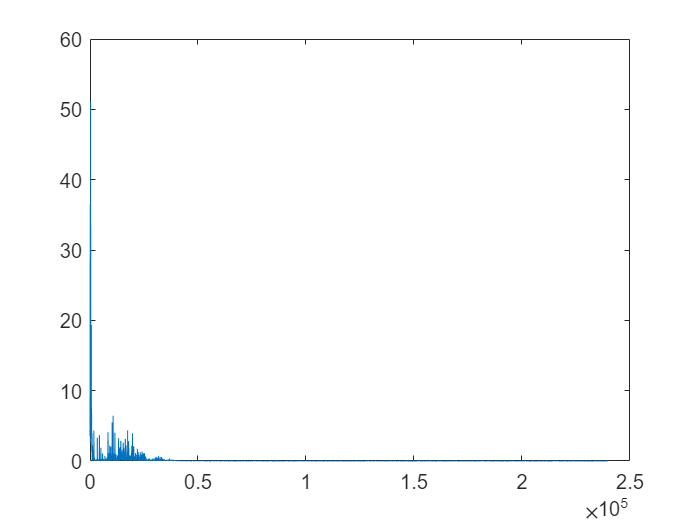

% Spectrum configurations
config.spec.nfft = config.data.rate * 10; % resolution = 0.1 Hz
config.spec.f = (1:ceil(config.spec.nfft / 2)) / config.spec.nfft * config.data.rate;

% Extract spectrums
for cnt = 1:config.data.nData

    for cnt2 = 1:size(data(1).detected, 3)
        spec = fft(data(cnt).detected(:,cnt2), config.spec.nfft); 
        data(cnt).spec(:,cnt2) = abs(spec(2:ceil(config.spec.nfft / 2 + 1))); 
        plot(data(cnt).spec)
    end

end

## Split data for calibration

% # of training data
config.calib.nTrain = 10;

% Include the empty and full data + intermediates
idx = ceil(linspace(1, config.data.nData / config.data.nTrial, config.calib.nTrain)); % Train data 선형 벡터 생성

idxFilter = false(1, config.data.nData); % 전체 0 
for cnt = 1:length(idx)
    idxFilter((idx(cnt) - 1) * config.data.nTrial + (1:config.data.nTrial)) = true; % 0 과 max만 true로 자동화
end

% Split data into two groups: train and test
train = data(idxFilter); % 학습을 할 때 사용할 데이터 / 0 ~ max amount
test = data(~idxFilter); % 우리가 학습한 모델의 성능을 테스트하는 데이터 / 0 과 max를 제외한 나머지 data

## Calibration #1: Compute a frequency range

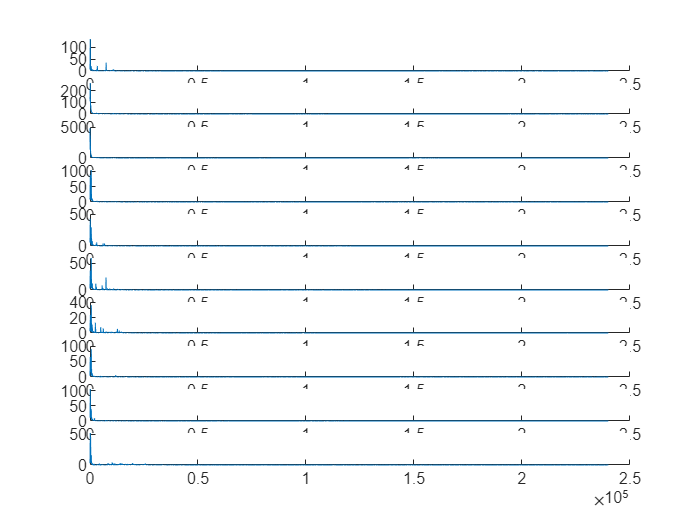

% Calibration configuration
% config.calib.distance = (config.spec.nfft / 2) * .1; 
config.calib.marginRatio = .01; 

% Determine a frequency search range using the empty & full data
clf
for cnt = [1, config.calib.nTrain] 
    % Combine multiple spectrums obtained with the same amount of water
    cur = [train((cnt - 1) * config.data.nTrial + (1:config.data.nTrial)).spec]; 
    cur = mean(cur ./ max(cur), 2);

    
    if cnt == 1
        [~, fPeak] = max(cur);
        calib.f0 = config.spec.f(fPeak); 
        calib.sRange(2) = calib.f0 * (1 + config.calib.marginRatio); 
    else
        [~, fPeak] = max(cur(1:fPeak)); 
        calib.sRange(1) = config.spec.f(fPeak) * (1 - config.calib.marginRatio); 
    end
end

% Determine a frequency for each training data
calib.spec = [];
calib.amount = []; 
calib.freq = [];


for cnt = 1:config.calib.nTrain
    range = (cnt - 1) * config.data.nTrial + (1:config.data.nTrial); 

    cur = [train(range).spec];

    subplot(config.calib.nTrain, 1, cnt)
    hold on 
    meanCur = mean(cur, 2);
    plot(meanCur)

    
    calib.spec(cnt, :) = mean(meanCur ./ max(meanCur), 2);
    calib.freq(cnt) = func_detectFreq(calib.spec(cnt, :), config.spec.f, calib.sRange);   
    calib.amount(cnt) = train(range(1)).amount;
end

## Calibration #2: Compute calibration parameters

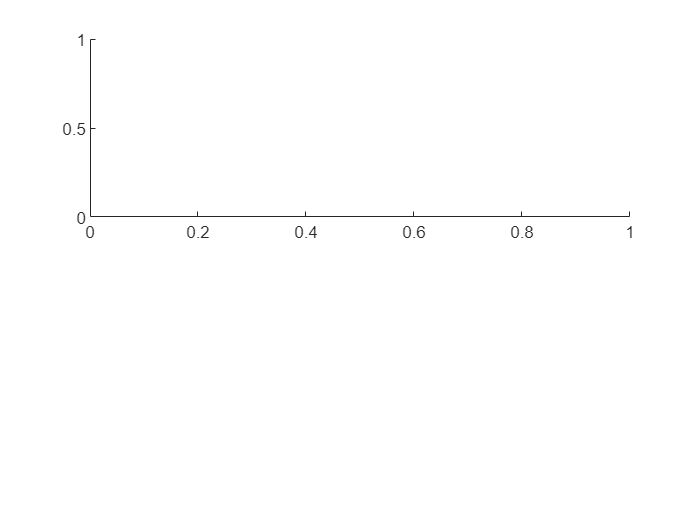

calib.french = func_computeFrenchParams(calib.amount', calib.freq', calib.f0, cup.maxAmount, 2); % A.P French's Formula
calib.damped = func_computeDampedParams(calib.amount', calib.freq', calib.f0); % Damped Oscillations

clf
subplot 211

plot(calib.french.f, calib.french.x, calib.french.y)

"f"은(는) 인식할 수 없는 필드 이름입니다.

title("french")
legend('off')

subplot 212
plot(calib.damped.f, calib.damped.x, calib.damped.y)
title("damped")
legend('off')

## Evaluation

result = struct();
for cnt = 1:length(test) / config.data.nTrial
    range = (cnt - 1) * config.data.nTrial + (1:config.data.nTrial); 
        
    result(cnt).truth = test(range(1)).amount;     
    
    meanCur = [test(range).spec];    
    result(cnt).spec = mean(meanCur ./ max(meanCur), 2);
    
    result(cnt).freq = func_detectFreq(result(cnt).spec, config.spec.f, calib.sRange);
    
    result(cnt).fEstimated = func_estimateAmountUsingFrench(calib.french.f.a, ...
        result(cnt).freq, calib.f0, cup.maxAmount, 2);    
    result(cnt).dEstimated = func_estimateAmountUsingDamped(calib.damped.f.a, ...
        result(cnt).freq, calib.f0, cup.maxAmount);
    result(cnt).mEstimated = mean([result(cnt).fEstimated, result(cnt).dEstimated]);
    
    result(cnt).fErr = abs(result(cnt).truth - result(cnt).fEstimated);
    result(cnt).dErr = abs(result(cnt).truth - result(cnt).dEstimated);
    result(cnt).mErr = abs(result(cnt).truth - result(cnt).mEstimated);
end

clf
subplot 311
plot([result(:).truth], [result(:).fErr])
title(['frenchErr =' num2str(mean([result(:).fErr]))])

subplot 312
plot([result(:).truth], [result(:).dErr])
title(['dampedErr =' num2str(mean([result(:).dErr]))])

subplot 313
plot([result(:).truth], [result(:).mErr])
title(['meanErr =' num2str(mean([result(:).mErr]))])